# Simulering Robot Arm

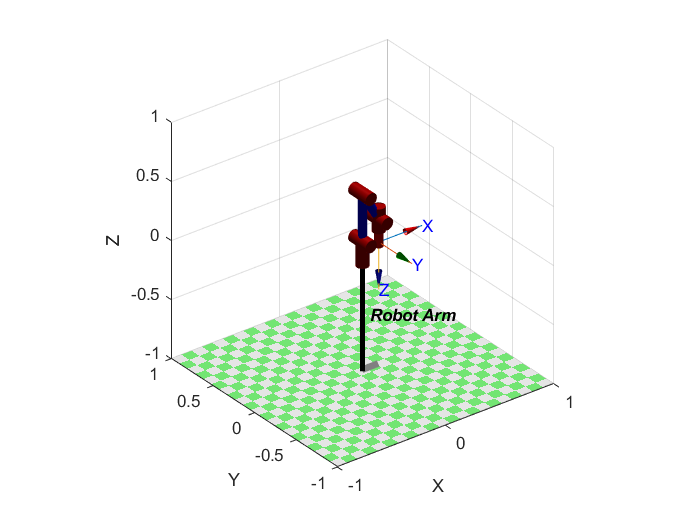

clear all
close all
clc
% Lengde links
L1 = 0.1; L2=0.4; L3=0.3; L4=0.2;
% DH-parameter
L(1) = Link('d', L1,'a',0,'alpha',pi/2);
L(2) = Link('d', 0,'a',L2,'alpha', 0);
L(3) = Link('d', 0,'a',L3,'alpha', 0);
L(4) = Link('d', 0,'a',0,'alpha', pi/2, 'offset', pi/2);
L(5) = Link('d', L4,'a',0,'alpha',0);
% Serial chain robot arm
Robot_Arm = SerialLink(L, 'name', 'Robot Arm');
% Joint limit
Robot_Arm.qlim = [[-pi pi]; [-pi*3/4 pi*3/4]; [-pi*3/4 pi*3/4]; [-pi*3/4 pi*3/4];[-pi pi];];
% Optional: Define tool rotation to give x forward, z upwards, using the 
% 'tool' member function of the SerialLink object. See more info on SE3 
% below.
%Robot_Arm.tool =SE3.Ry(pi/2) * SE3.Rz(-pi)
Robot_Arm.plot([0 pi/2 -pi*5/6 -pi/6 0])

% Define area to simulate robot in, as default values are too tight. This
% should then be passed when calling the plot function, with option
% 'workspace'.
W = [-4 4 -4 4 -4 4] 

W =     -4     4    -4     4    -4     4



% Resting pose [0 pi/2 pi*5/6 pi/6 0]
T1 = Robot_Arm.fkine([0 pi/2 -pi*5/6 -pi/6 0])

 

T1 = 
         1         0         0      0.15
         0        -1         0         0
         0         0        -1   0.04019
         0         0         0         1


q1 = Robot_Arm.ikine(T1,'mask',[1 1 1 0 1 1])

q1 =     0.0000    1.5708   -2.6180   -0.5236    0.0000



T2 = SE3(0.5, 0, -0.17)*SE3.Ry(pi/3)

 

T2 = 
    0.5000         0    0.8660       0.5
         0         1         0         0
   -0.8660         0    0.5000     -0.17
         0         0         0         1


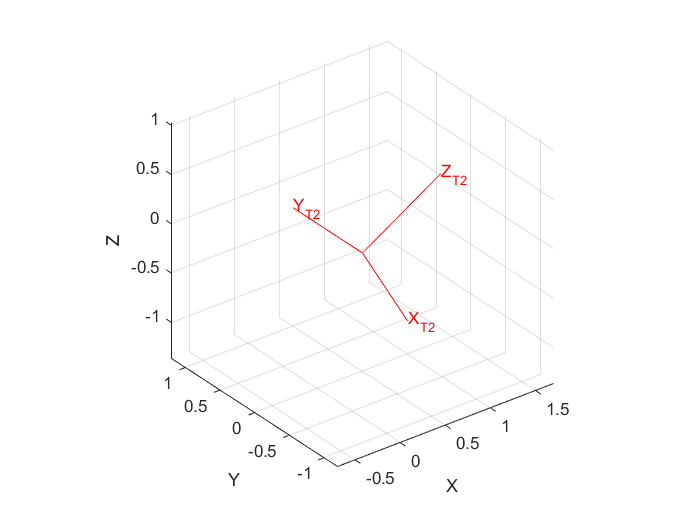

%Tg = T2.T
trplot(T2,'color','r','frame','T2')


% q_guess = Tg(1,:);
q2 = Robot_Arm.ikine(T2,'mask',[1 1 1 0 1 1],'q0',q1);

Ts = jtraj(q1, q2, 50);


%Robot_Arm.plot(qc)